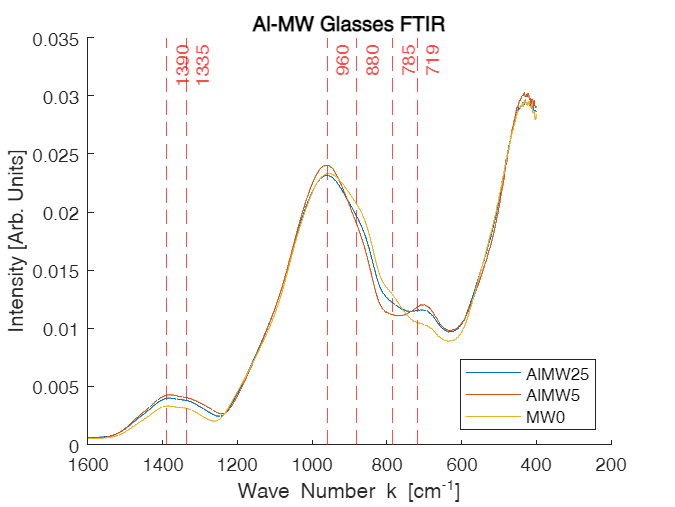

%A script that opens all csvs in a a specified directory and does a bunch
%of FTIR plots.

%clearing crap
clear all
clf

%selecting fodler to loop through
folder = "C:\Users\Jack\MATLAB Drive\PhD Work\FTIR Plotter_030624\Padova\";
tit = "Al-MW Glasses FTIR";

%extracting full list of files
files = dir(fullfile(folder, "*.csv"));

%looping through and importing all folders
for i = 1:length(files)

    %full file path
    path = fullfile(folder, files(i).name);

    import = readtable(path);
    
    %plotting data
    plot(import{:,1},import{:,2})
    hold on %plotting on same graph

    %checking if we are on the first to set up storage and store x axis
    if i == 1

        data = import;
    
    else % data should always exist after this else

        %concatenating columns
        data = [data, import(:,2)]; 


    end
     
end

%extra vertical lines
xline([1390 1335 960 880 785 719], "--", ["1390" "1335" "960" "880" "785" "719"], "color","red");

%labelling gprah
xlabel("Wave Number k [cm^{-1}]")
ylabel("Intensity [Arb. Units]")
title(tit)
legend(data.Properties.VariableNames{2:end},"Location","SouthEast"); % Omitting the first column header

%beautifying curve
ax = gca;
ax.XAxisLocation = "origin";
% ax.YAxisLocation = "origin";
set(gca, 'xdir','reverse');
box off;

hold off %ending plotting